## 数据导入-安徽省

filename = 'D:\Drivers\CarbonEmissiondata\Anhui_data.xlsx'; 
dataTable = readtable(filename);

dataGDP_ren = dataTable.Per_capita_GDP_yuan(1:25);
dataGDP = dataGDP_ren.';

dataPopulation_wan = dataTable.Population_wan(1:25);
dataPopulation = dataPopulation_wan.';
disp(dataPopulation)

   1.0e+03 *

    6.0197    6.0452    6.0707    6.0930    6.1280    6.1440    6.1630    6.2280    6.1200    6.1100    6.1180    6.1350    6.1310    5.9570    5.9720    5.9780    5.9880    5.9970    6.0110    6.0330    6.0570    6.0760    6.0920    6.1050    6.1130



dataSecond_billion = dataTable.Value_added_of_the_secondary_industry_billion(1:25);
dataSecond = dataSecond_billion.';

dataCE_mt = dataTable.CarbonEmissions_mt(1:25);
%dataCE = dataCE_mt.';

dataCoal_tons = dataTable.Coal_consumption_10000_tons(1:25);
dataCoke_tons = dataTable.Coke_consumption_10000_tons(1:25);
dataFuel_tons = dataTable.Fuel_oil_consumption_10000_tons(1:25);
energyconsumption= (dataCoal_tons+dataCoke_tons+dataFuel_tons);
dataEnergy = energyconsumption.';
disp(dataEnergy)

   1.0e+04 *

    0.5857    0.6184    0.6335    0.6788    0.7197    0.7543    0.8423    0.8787    0.9293    0.9928    1.1045    1.2655    1.3977    1.4763    1.5970    1.6122    1.7266    1.7601    1.7527    1.7433    1.7885    1.8506    1.8520    1.8939    1.9256




dataNatural_meters = dataTable.Natural_gas_consumption_billion_cubic_meters(1:25);
dataNaturalgas = dataNatural_meters.';

dataTechnology_million = dataTable.Technology_market_transaction_volume_100_million_yuan(1:25);
dataTechnology = dataTechnology_million.';

%dataFirepower_kilowatt= dataTable.Thermal_power_generation_100_million_kilowatt_hours(1:26);
%dataFire = dataFirepower_kilowatt.';

dataWaterpower_kilowatt= dataTable.Hydroelectric_power_generation_100_million_kilowatt_hours(1:25);
%dataWater = dataWaterpower_kilowatt.';

dataTotalpower_kilowatt= dataTable.Total_power_generation_100_million_kilowatt_hours(1:25);
%dataTotalfadian = dataTotalpower_kilowatt.';
%dataWaterpercent_2=(dataWaterpower_kilowatt/dataTotalpower_kilowatt);
%dataWaterpercent=dataWaterpercent_2.';


## 人均GDP的LSTM模型

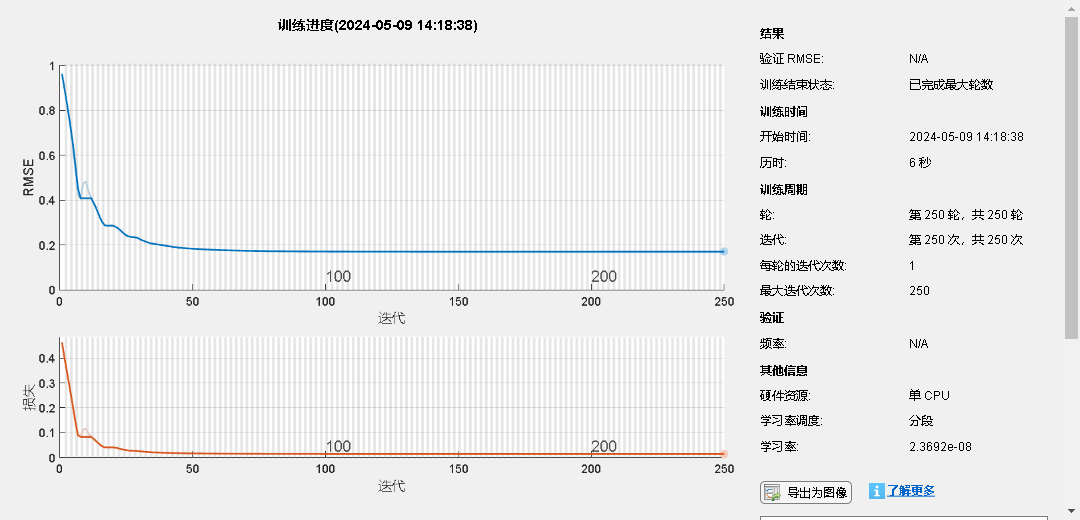

numTimeStepsTrain = numel(dataGDP); 
dataTrainGDP = dataGDP(1 : numTimeStepsTrain);
% 数据标准化，零均值和单位方差
muGDP = mean(dataTrainGDP);
sigGDP = std(dataTrainGDP);
dataTrainStandardizedGDP = (dataTrainGDP - muGDP) / sigGDP;
% 训练数据
XTrainGDP = dataTrainStandardizedGDP(1:end-1);
YTrainGDP = dataTrainStandardizedGDP(2:end);
% 创建 LSTM 网络
numFeaturesGDP = 1;
numResponsesGDP = 1;
numHiddenUnitsGDP = 50;

layersGDP = [sequenceInputLayer(numFeaturesGDP)
          lstmLayer(numHiddenUnitsGDP)
          fullyConnectedLayer(numResponsesGDP)
          regressionLayer];

% 设置网络参数
optionsGDP = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 10, ...
    'LearnRateDropFactor', 0.6, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');

% 训练
netGDP = trainNetwork(XTrainGDP, YTrainGDP, layersGDP, optionsGDP);

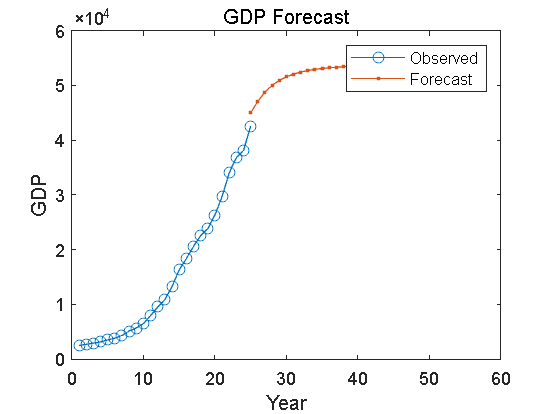

% 预测
netGDP = predictAndUpdateState(netGDP, XTrainGDP);
% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netGDP, YPredGDP] = predictAndUpdateState(netGDP, YTrainGDP(end));

% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictGDP = 28;
YPredGDP = [YPredGDP zeros(1, numYearsToPredictGDP - 1)]; % 预分配预测数组
for i = 2:numYearsToPredictGDP
    [netGDP, YPredGDP(:, i)] = predictAndUpdateState(netGDP, YPredGDP(:, i-1), 'ExecutionEnvironment', 'cpu');
end
% 去标准化
YPredGDP = sigGDP * YPredGDP + muGDP;
% 画图
figure;
plot(1:numel(dataGDP), dataGDP, '-o')
hold on
idx = numel(dataGDP) : (numel(dataGDP) + numYearsToPredictGDP - 1);
plot(idx, YPredGDP, '.-')
hold off 
xlabel("Year");
ylabel("GDP");
title("GDP Forecast");
legend("Observed", "Forecast");

%writematrix(YPred, 'D:\Drivers\LSTM_liaoningCEdata.xlsx'); % 修改为实际文件路径
disp(YPredGDP)

   1.0e+04 *

    4.4954    4.7095    4.8751    4.9991    5.0904    5.1572    5.2065    5.2433    5.2709    5.2921    5.3084    5.3211    5.3312    5.3392    5.3457    5.3509    5.3551    5.3586    5.3614    5.3638    5.3657    5.3673    5.3687    5.3698    5.3708    5.3716    5.3722    5.3728



## 人口的LSTM模型

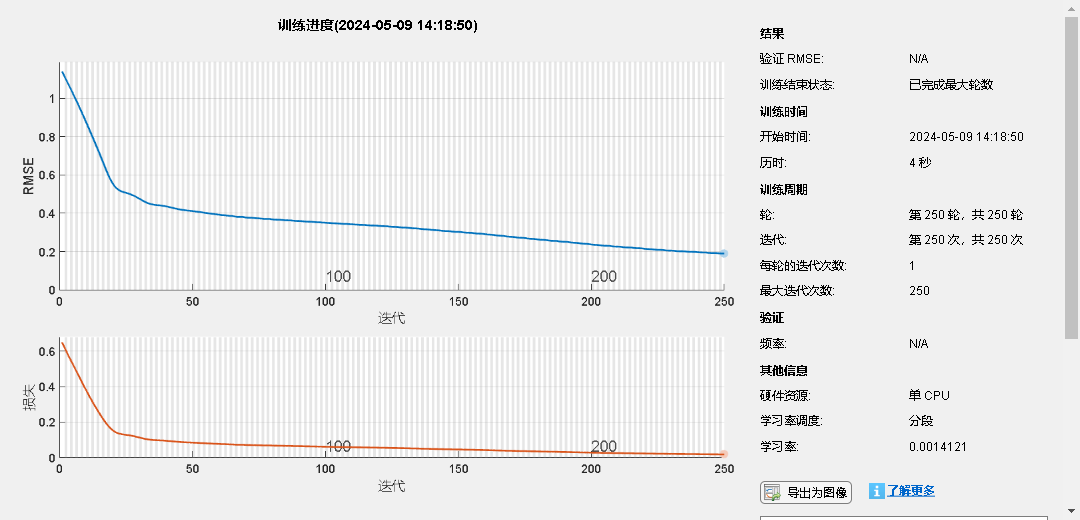

numTimeStepsTrainPopulation = numel(dataPopulation); 
dataTrainPopulation = dataPopulation(1 : numTimeStepsTrainPopulation);

% 数据标准化，零均值和单位方差
muPopulation = mean(dataTrainPopulation);
sigPopulation = std(dataTrainPopulation);
dataTrainStandardizedPopulation = (dataTrainPopulation - muPopulation) / sigPopulation;

% 训练数据
XTrainPopulation = dataTrainStandardizedPopulation(1:end-1);
YTrainPopulation = dataTrainStandardizedPopulation(2:end);

% 创建 LSTM 网络
numFeaturesPopulation = 1;
numResponsesPopulation = 1;
numHiddenUnitsPopulation = 20;

layersPopulation = [sequenceInputLayer(numFeaturesPopulation)
          lstmLayer(numHiddenUnitsPopulation)
          fullyConnectedLayer(numResponsesPopulation)
          regressionLayer];

% 设置网络参数
optionsPopulation = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 20, ...
    'LearnRateDropFactor', 0.9, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');

% 训练
netPopulation = trainNetwork(XTrainPopulation, YTrainPopulation, layersPopulation, optionsPopulation);

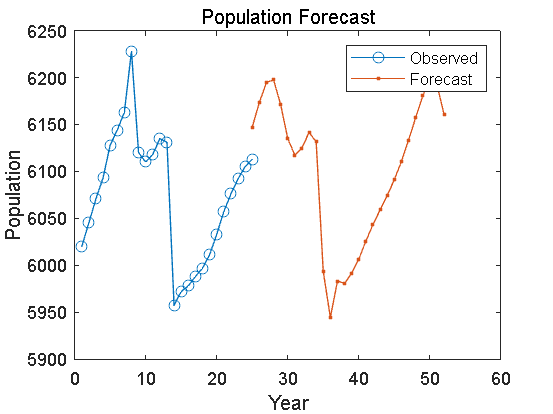


% 预测
netPopulation = predictAndUpdateState(netPopulation, XTrainPopulation);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netPopulation, YPredPopulation] = predictAndUpdateState(netPopulation, YTrainPopulation(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictPopulation = 28;
YPredPopulation = [YPredPopulation zeros(1, numYearsToPredictPopulation - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictPopulation
    [netPopulation, YPredPopulation(:, i)] = predictAndUpdateState(netPopulation, YPredPopulation(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredPopulation = sigPopulation * YPredPopulation + muPopulation;
% 画图
figure;
plot(1:numel(dataPopulation), dataPopulation, '-o')
hold on
idx = numel(dataPopulation) : (numel(dataPopulation) + numYearsToPredictPopulation - 1);
plot(idx, YPredPopulation, '.-')
hold off 
xlabel("Year");
ylabel("Population");
title("Population Forecast");
legend("Observed", "Forecast");

disp(YPredPopulation)

   1.0e+03 *

    6.1471    6.1734    6.1946    6.1976    6.1712    6.1351    6.1174    6.1249    6.1415    6.1317    5.9931    5.9445    5.9831    5.9807    5.9915    6.0065    6.0256    6.0435    6.0591    6.0743    6.0910    6.1105    6.1331    6.1570    6.1803    6.1978    6.1926    6.1609



## 第二产业的LSTM模型

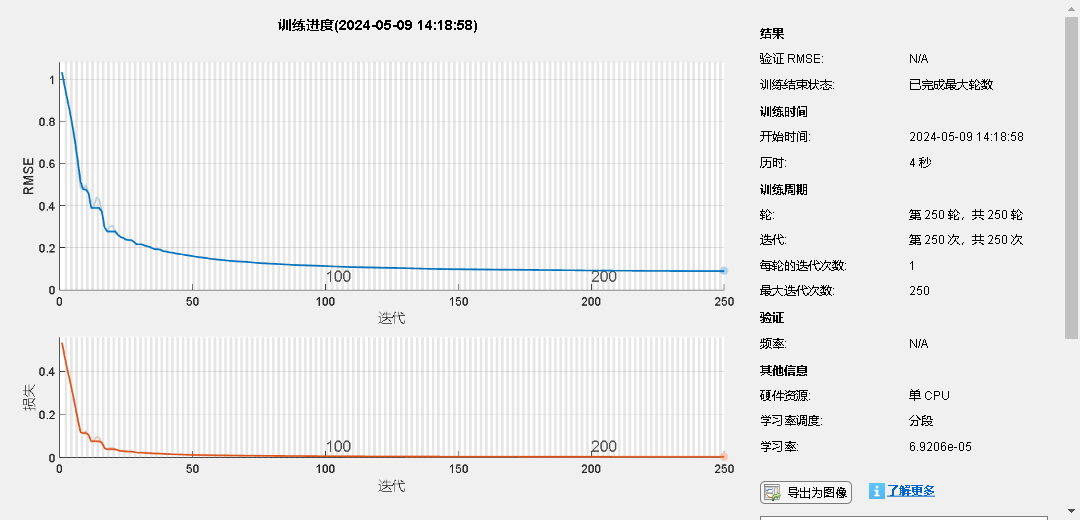

%dataSecond = [20.75, 18.89, 18.75, 20.15, 18.93, 18.81, 18.82, 15.81, 14.81, 13.1, 14.24, 16.21, 16.44, 19.02, 39.07, 63.72, 78.68, 84, 55.35, 50.63, 62.05, 73.16, 75.01, 71.46727273, 74.42867589, 74.39];
numTimeStepsTrainSecond = numel(dataSecond); 
dataTrainSecond = dataSecond(1 : numTimeStepsTrainSecond);

% 数据标准化，零均值和单位方差
musecond = mean(dataTrainSecond);
sigsecond = std(dataTrainSecond);
dataTrainStandardizedSecond = (dataTrainSecond - musecond) / sigsecond;

% 训练数据
XTrainSecond = dataTrainStandardizedSecond(1:end-1);
YTrainSecond = dataTrainStandardizedSecond(2:end);

% 创建 LSTM 网络
numFeaturesSecond= 1;
numResponsesSecond = 1;
numHiddenUnitsSecond = 40;

layersSecond = [sequenceInputLayer(numFeaturesSecond)
          lstmLayer(numHiddenUnitsSecond)
          fullyConnectedLayer(numResponsesSecond)
          regressionLayer];

% 设置网络参数
optionsSecond = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 20, ...
    'LearnRateDropFactor', 0.7, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');

% 训练
netSecond = trainNetwork(XTrainSecond, YTrainSecond, layersSecond, optionsSecond);

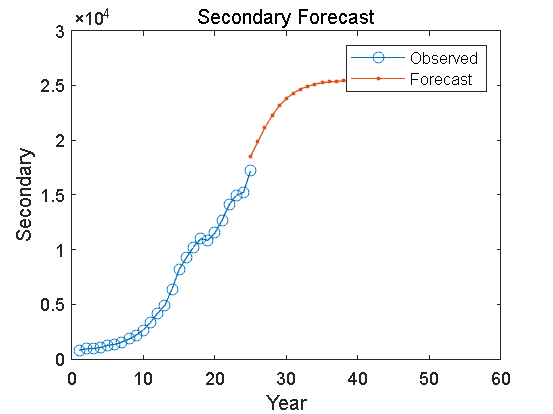


% 预测
netSecond = predictAndUpdateState(netSecond, XTrainSecond);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netSecond, YPredSecond] = predictAndUpdateState(netSecond, YTrainSecond(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictSecond = 28;
YPredSecond = [YPredSecond zeros(1, numYearsToPredictSecond - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictSecond
    [netSecond, YPredSecond(:, i)] = predictAndUpdateState(netSecond, YPredSecond(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredSecond = sigsecond * YPredSecond + musecond;
% 画图
figure;
plot(1:numel(dataSecond), dataSecond, '-o')
hold on
idx = numel(dataSecond) : (numel(dataSecond) + numYearsToPredictSecond - 1);
plot(idx, YPredSecond, '.-')
hold off 
xlabel("Year");
ylabel("Secondary");
title("Secondary Forecast");
legend("Observed", "Forecast");

disp(YPredSecond)

   1.0e+04 *

    1.8475    1.9868    2.1146    2.2237    2.3118    2.3796    2.4300    2.4665    2.4925    2.5108    2.5234    2.5318    2.5373    2.5405    2.5422    2.5427    2.5423    2.5413    2.5397    2.5378    2.5356    2.5332    2.5306    2.5278    2.5249    2.5220    2.5189    2.5158



## 煤炭等化石能源消耗量的LSTM模型

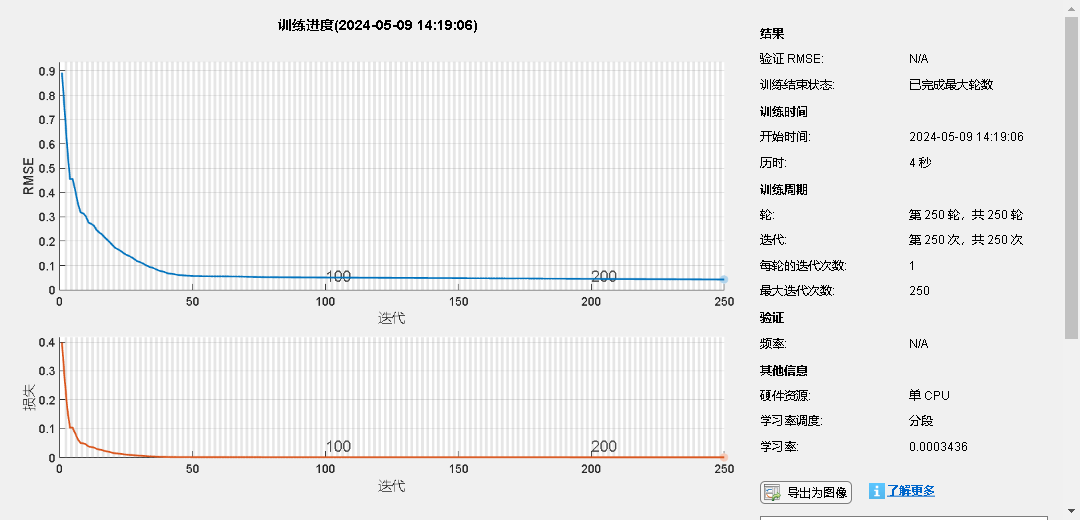

numTimeStepsTrainEnergy = numel(dataEnergy); 
dataTrainEnergy = dataEnergy(1 : numTimeStepsTrainEnergy);

% 数据标准化，零均值和单位方差
muEnergy = mean(dataTrainEnergy);
sigEnergy = std(dataTrainEnergy);
dataTrainStandardizedEnergy = (dataTrainEnergy - muEnergy) / sigEnergy;

% 训练数据
XTrainEnergy = dataTrainStandardizedEnergy(1:end-1);
YTrainEnergy = dataTrainStandardizedEnergy(2:end);

% 创建 LSTM 网络
numFeaturesEnergy= 1;
numResponsesEnergy = 1;
numHiddenUnitsEnergy = 100;

layersEnergy = [sequenceInputLayer(numFeaturesEnergy)
          lstmLayer(numHiddenUnitsEnergy)
          fullyConnectedLayer(numResponsesEnergy)
          regressionLayer];

% 设置网络参数
optionsEnergy = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 20, ...
    'LearnRateDropFactor', 0.8, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');
%不同化石能源消耗背景下，改这个就行LearnRateDropFactor'/但怎么解释呢？
% 训练
netEnergy = trainNetwork(XTrainEnergy, YTrainEnergy, layersEnergy, optionsEnergy);

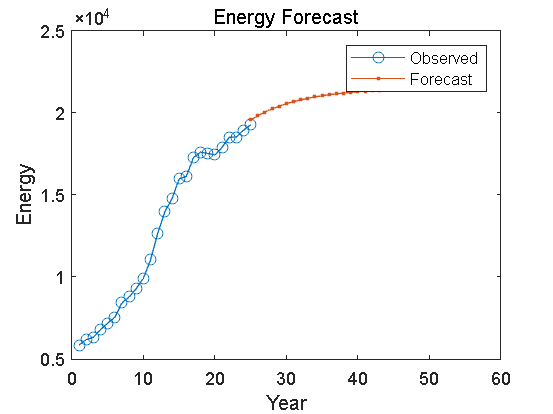


% 预测
netEnergy = predictAndUpdateState(netEnergy, XTrainEnergy);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netEnergy, YPredEnergy] = predictAndUpdateState(netEnergy, YTrainEnergy(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictEnergy = 28;
YPredEnergy = [YPredEnergy zeros(1, numYearsToPredictEnergy - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictEnergy
    [netEnergy, YPredEnergy(:, i)] = predictAndUpdateState(netEnergy, YPredEnergy(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredEnergy = sigEnergy * YPredEnergy + muEnergy;
% 画图
figure;
plot(1:numel(dataEnergy), dataEnergy, '-o')
hold on
idx = numel(dataEnergy) : (numel(dataEnergy) + numYearsToPredictEnergy - 1);
plot(idx, YPredEnergy, '.-')
hold off 
xlabel("Year");
ylabel("Energy");
title("Energy Forecast");
legend("Observed", "Forecast");

disp(YPredEnergy)

   1.0e+04 *

    1.9559    1.9817    2.0041    2.0235    2.0403    2.0548    2.0674    2.0783    2.0878    2.0960    2.1032    2.1095    2.1150    2.1199    2.1241    2.1278    2.1310    2.1339    2.1364    2.1386    2.1406    2.1423    2.1439    2.1452    2.1464    2.1475    2.1484    2.1492



## 天然气的LSTM模型

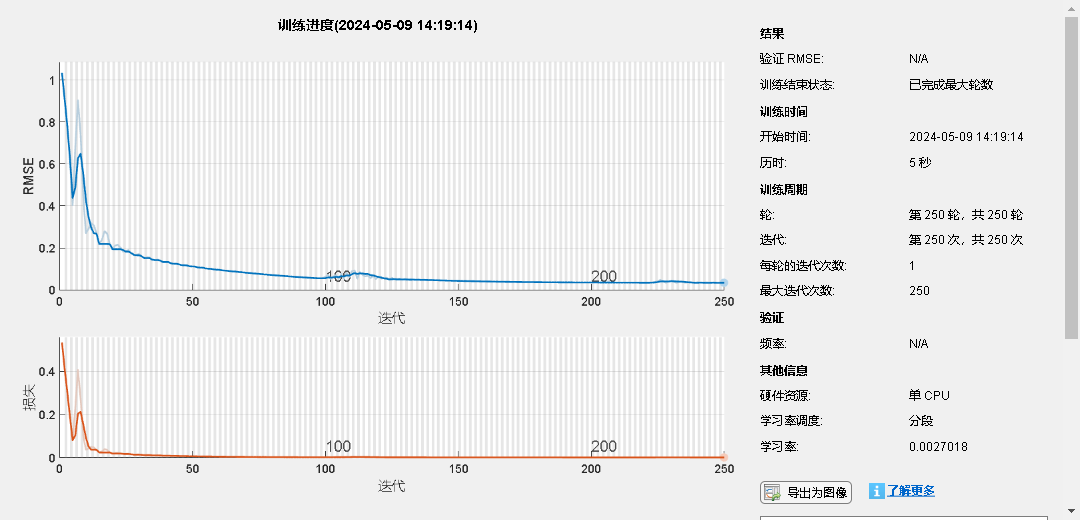

numTimeStepsTrainNaturalgas = numel(dataNaturalgas); 
dataTrainNaturalgas = dataNaturalgas(1 : numTimeStepsTrainNaturalgas);

% 数据标准化，零均值和单位方差
muNaturalgas = mean(dataTrainNaturalgas);
sigNaturalgas = std(dataTrainNaturalgas);
dataTrainStandardizedNaturalgas = (dataTrainNaturalgas - muNaturalgas) / sigNaturalgas;

% 训练数据
XTrainNaturalgas = dataTrainStandardizedNaturalgas(1:end-1);
YTrainNaturalgas = dataTrainStandardizedNaturalgas(2:end);

% 创建 LSTM 网络
numFeaturesNaturalgas= 1;
numResponsesNaturalgas = 1;
numHiddenUnitsNaturalgas = 100;

layersNaturalgas = [sequenceInputLayer(numFeaturesNaturalgas)
          lstmLayer(numHiddenUnitsNaturalgas)
          fullyConnectedLayer(numResponsesNaturalgas)
          regressionLayer];

% 设置网络参数
optionsNaturalgas = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 20, ...
    'LearnRateDropFactor', 0.95, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');
%不同Naturalgas背景下，改这个就行LearnRateDropFactor'
% 训练
netNaturalgas = trainNetwork(XTrainNaturalgas, YTrainNaturalgas, layersNaturalgas, optionsNaturalgas);

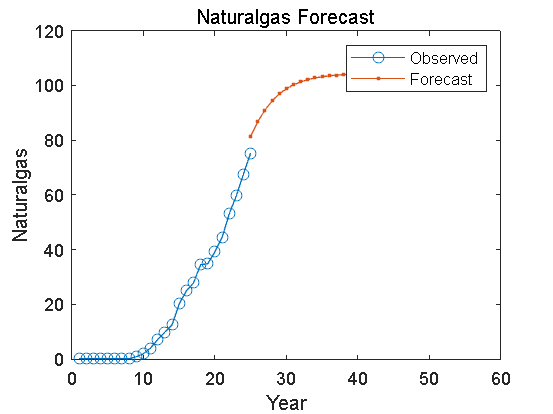


% 预测
netNaturalgas = predictAndUpdateState(netNaturalgas, XTrainNaturalgas);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netNaturalgas, YPredNaturalgas] = predictAndUpdateState(netNaturalgas, YTrainNaturalgas(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictNaturalgas = 28;
YPredNaturalgas = [YPredNaturalgas zeros(1, numYearsToPredictNaturalgas - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictNaturalgas
    [netNaturalgas, YPredNaturalgas(:, i)] = predictAndUpdateState(netNaturalgas, YPredNaturalgas(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredNaturalgas = sigNaturalgas * YPredNaturalgas + muNaturalgas;
% 画图
figure;
plot(1:numel(dataNaturalgas), dataNaturalgas, '-o')
hold on
idx = numel(dataNaturalgas) : (numel(dataNaturalgas) + numYearsToPredictNaturalgas - 1);
plot(idx, YPredNaturalgas, '.-')
hold off 
xlabel("Year");
ylabel("Naturalgas");
title("Naturalgas Forecast");
legend("Observed", "Forecast");

disp(YPredNaturalgas)

   81.4479   86.7363   90.9831   94.3027   96.8458   98.7686  100.2110  101.2886  102.0925  102.6927  103.1418  103.4790  103.7331  103.9255  104.0718  104.1836  104.2695  104.3358  104.3871  104.4270  104.4581  104.4825  104.5016  104.5167  104.5285  104.5377  104.5450  104.5507



## 科技发展LSTM模型

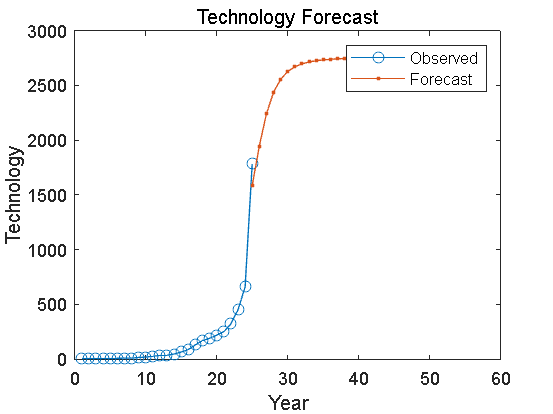

numTimeStepsTrainTechnology = numel(dataTechnology); 
dataTrainTechnology = dataTechnology(1 : numTimeStepsTrainTechnology);

% 数据标准化，零均值和单位方差
muTechnology = mean(dataTrainTechnology);
sigTechnology = std(dataTrainTechnology);
dataTrainStandardizedTechnology = (dataTrainTechnology - muTechnology) / sigTechnology;

% 训练数据
XTrainTechnology = dataTrainStandardizedTechnology(1:end-1);
YTrainTechnology = dataTrainStandardizedTechnology(2:end);

% 创建 LSTM 网络
numFeaturesTechnology= 1;
numResponsesTechnology = 1;
numHiddenUnitsTechnology = 100;

layersTechnology = [sequenceInputLayer(numFeaturesTechnology)
          lstmLayer(numHiddenUnitsTechnology)
          fullyConnectedLayer(numResponsesTechnology)
          regressionLayer];

% 设置网络参数
optionsTechnology = trainingOptions('adam', ...
    'MaxEpochs', 250, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.005, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 10, ...
    'LearnRateDropFactor', 0.1, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');
%不同Water背景下，'LearnRateDropFactor', 0.92大概会在2033碳达峰 ，0.95大概2030年...
% 训练
netTechnology = trainNetwork(XTrainTechnology, YTrainTechnology, layersTechnology, optionsTechnology);

% 预测
netTechnology = predictAndUpdateState(netTechnology, XTrainTechnology);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netTechnology, YPredTechnology] = predictAndUpdateState(netTechnology, YTrainTechnology(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictTechnology = 28;
YPredTechnology = [YPredTechnology zeros(1, numYearsToPredictTechnology - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictTechnology
    [netTechnology, YPredTechnology(:, i)] = predictAndUpdateState(netTechnology, YPredTechnology(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredTechnology = sigTechnology * YPredTechnology + muTechnology;
% 画图
figure;
plot(1:numel(dataTechnology), dataTechnology, '-o')
hold on
idx = numel(dataTechnology) : (numel(dataTechnology) + numYearsToPredictTechnology - 1);
plot(idx, YPredTechnology, '.-')
hold off 
xlabel("Year");
ylabel("Technology");
title("Technology Forecast");
legend("Observed", "Forecast");

disp(YPredTechnology)

   1.0e+03 *

    1.5853    1.9457    2.2398    2.4363    2.5558    2.6267    2.6695    2.6962    2.7135    2.7250    2.7329    2.7384    2.7424    2.7452    2.7474    2.7489    2.7501    2.7511    2.7518    2.7523    2.7528    2.7531    2.7534    2.7536    2.7538    2.7539    2.7541    2.7542



## 水力发电的百分占比LSTM模型

dataWaterpercent_2= dataTable.WaterPercent(1:25);
dataWaterpercent_1=dataWaterpercent_2;
%dataTotalfadian = dataTotalpower_kilowatt.';
%dataWaterpercent_1=(dataWaterpower_kilowatt / dataTotalpower_kilowatt)*100;
dataWaterpercent=dataWaterpercent_1.';
disp(dataWaterpercent);

    9.6900    9.9100    9.6100    4.5800    8.4100   10.5100   15.6000   18.1100   12.5200   15.7200   19.6700   28.1400   16.3900   18.8500   17.9000   19.6200   34.1500   41.5100   48.6700   63.1700   52.9700   53.8400   51.0900   66.2100   69.4167



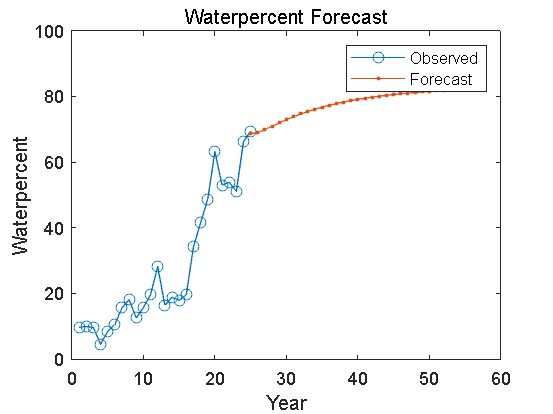


numTimeStepsTrainWaterpercent = numel(dataWaterpercent); % 使用所有的数据来训练
dataTrainWaterpercent = dataWaterpercent(1 : numTimeStepsTrainWaterpercent);

% 数据标准化，零均值和单位方差
muWaterpercent = mean(dataTrainWaterpercent);
sigWaterpercent = std(dataTrainWaterpercent);
dataTrainStandardizedWaterpercent = (dataTrainWaterpercent - muWaterpercent) / sigWaterpercent;

% 训练数据
XTrainWaterpercent = dataTrainStandardizedWaterpercent(1:end-1);
YTrainWaterpercent = dataTrainStandardizedWaterpercent(2:end);

% 创建 LSTM 网络
numFeaturesWaterpercent= 1;
numResponsesWaterpercent = 1;
numHiddenUnitsWaterpercent = 130;

layersWaterpercent = [sequenceInputLayer(numFeaturesWaterpercent)
          lstmLayer(numHiddenUnitsWaterpercent)
          fullyConnectedLayer(numResponsesWaterpercent)
          regressionLayer];

% 设置网络参数
optionsWaterpercent = trainingOptions('adam', ...
    'MaxEpochs', 550, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.05, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 20, ...
    'LearnRateDropFactor', 0.1, ...
    'Verbose', 0, ...
    'Plots', 'training-progress');
%不同Water背景下，改这个就'LearnRateDropFactor', 0.92大概会在2033碳达峰 ，0.95大概2030年...
% 训练
netWaterpercent = trainNetwork(XTrainWaterpercent, YTrainWaterpercent, layersWaterpercent, optionsWaterpercent);

% 预测
netWaterpercent = predictAndUpdateState(netWaterpercent, XTrainWaterpercent);

% 使用训练响应的最后一个时间步 YTrain(end) 进行第一次预测
[netWaterpercent, YPredWaterpercent] = predictAndUpdateState(netWaterpercent, YTrainWaterpercent(end));
% 循环其余预测，使用前一次的预测结果作为输入
numYearsToPredictWaterpercent = 28;
YPredWaterpercent = [YPredWaterpercent zeros(1, numYearsToPredictWaterpercent - 1)]; % 预分配预测数组

for i = 2:numYearsToPredictWaterpercent
    [netWaterpercent, YPredWaterpercent(:, i)] = predictAndUpdateState(netWaterpercent, YPredWaterpercent(:, i-1), 'ExecutionEnvironment', 'cpu');
end

% 去标准化
YPredWaterpercent = sigWaterpercent * YPredWaterpercent + muWaterpercent;
% 画图
figure;
plot(1:numel(dataWaterpercent), dataWaterpercent, '-o')
hold on
idx = numel(dataWaterpercent) : (numel(dataWaterpercent) + numYearsToPredictWaterpercent - 1);
plot(idx, YPredWaterpercent, '.-')
hold off 
xlabel("Year");
ylabel("Waterpercent");
title("Waterpercent Forecast");
legend("Observed", "Forecast");

disp(YPredWaterpercent)

   68.6491   68.9566   69.8489   70.8834   71.9081   72.8792   73.7827   74.6145   75.3749   76.0667   76.6945   77.2634   77.7792   78.2472   78.6722   79.0589   79.4111   79.7324   80.0259   80.2943   80.5400   80.7653   80.9722   81.1624   81.3375   81.4989   81.6480   81.7860



## 原始STRIPAT模型

filename = 'D:\Drivers\CarbonEmissiondata\Anhui_data.xlsx'; 
dataTable = readtable(filename);

dataPopulation = dataTable.Population_wan(1:25) * 1e4;
dataGDP = dataTable.Per_capita_GDP_yuan(1:25); 
dataTechnology = dataTable.Technology_market_transaction_volume_100_million_yuan(1:25); % 技术市场交易量
dataEmission = dataTable.CarbonEmissions_mt(1:25); 

% 创建数据矩阵
dataMatrix = [dataPopulation, dataGDP, dataTechnology, dataEmission];

% 对数转换
dataLog = log(dataMatrix + 1); % 加1是为了避免对0取对数

% 将对数转换后的数据转换为dataTable
dataTableLog = array2table(dataLog, 'VariableNames', {'LogPopulation', 'LogGDP', 'LogTechnology', 'LogEmission'});

% 计算 Pearson 相关矩阵
correlationMatrix = corr(dataLog, 'Type', 'Pearson');

% 变量名
variableNames = {'Population', 'GDP', 'Technology', 'Emission'};

% 显示相关性矩阵
disp('Pearson Correlation Matrix:');

Pearson Correlation Matrix:


disp(array2table(correlationMatrix, 'VariableNames', variableNames, 'RowNames', variableNames));

                  Population      GDP       Technology    Emission
                  __________    ________    __________    ________

    Population            1     -0.32712     -0.26769     -0.39995
    GDP            -0.32712            1      0.98318      0.98513
    Technology     -0.26769      0.98318            1       0.9474
    Emission       -0.39995      0.98513       0.9474            1




% 绘制热力图
%figure;
%h = heatmap(variableNames, variableNames, correlationMatrix);
%h.Title = 'Pearson Correlation Matrix Heatmap';
%h.Colormap = bone; % 颜色映射选择
%h.ColorScaling = 'scaledcolumns'; % 颜色标准化

% 拟合模型
lm_formula = 'LogEmission ~ LogPopulation + LogGDP + LogTechnology';
model = fitlm(dataTableLog, lm_formula);
disp(model);

线性回归模型:
    LogEmission ~ 1 + LogPopulation + LogGDP + LogTechnology

估计系数:
                     Estimate       SE        tStat       pValue  
                     ________    ________    _______    __________

    (Intercept)        41.546       22.76     1.8254      0.082205
    LogPopulation     -2.3811      1.2578     -1.893      0.072222
    LogGDP            0.77771    0.077663     10.014    1.8907e-09
    LogTechnology    -0.15613     0.04207    -3.7112     0.0012933


观测值数目: 25，误差自由度: 21
均方根误差: 0.062
R 方: 0.986，调整 R 方 0.984
F 统计量(常量模型): 502，p 值 = 1.06e-19


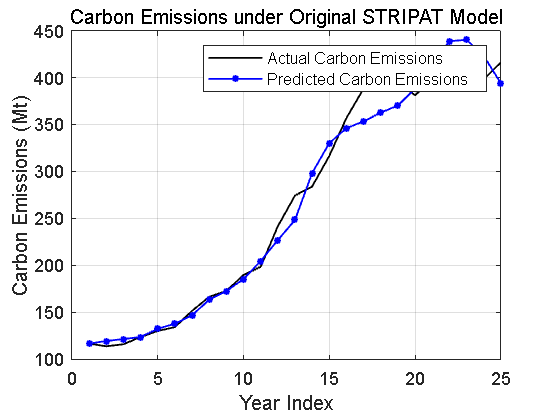


% 原始结果曲线图
figure;
plot(exp(dataTableLog.LogEmission), 'k', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Actual Carbon Emissions');
hold on;
predictedCE = predict(model, dataTableLog);
plot(exp(predictedCE), 'b-*', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Predicted Carbon Emissions');
title('Carbon Emissions under Original STRIPAT Model');
xlabel('Year Index');
ylabel('Carbon Emissions (Mt)');
legend('show');
grid on;
hold off;

## 改良STRIPAT模型

filename = 'D:\Drivers\CarbonEmissiondata\Anhui_data.xlsx'; 
dataTable = readtable(filename);

% 数据提取与转换 重新提取一下 变原单位
dataGDP = dataTable.Per_capita_GDP_yuan(1:25);
dataPopulation = dataTable.Population_wan(1:25) * 1e4;
dataSecond = dataTable.Value_added_of_the_secondary_industry_billion(1:25) * 1e9;
dataCE = dataTable.CarbonEmissions_mt(1:25);
energyconsumption = (dataTable.Coal_consumption_10000_tons(1:25) + dataTable.Coke_consumption_10000_tons(1:25) + dataTable.Fuel_oil_consumption_10000_tons(1:25)) * 1e4;
dataNaturalgas = dataTable.Natural_gas_consumption_billion_cubic_meters(1:25) * 1e9;
dataTechnology = dataTable.Technology_market_transaction_volume_100_million_yuan(1:25) * 1e8;
hydroPower = dataTable.Hydroelectric_power_generation_100_million_kilowatt_hours(1:25) * 1e8;
totalPower = dataTable.Total_power_generation_100_million_kilowatt_hours(1:25) * 1e8;
dataWaterPercent = (hydroPower ./ totalPower) * 100;

% 数据标准化处理
dataMatrix = [dataCE, dataGDP, dataPopulation, dataSecond, energyconsumption, dataNaturalgas, dataTechnology, dataWaterPercent];

% 对数转换，直接处理
dataLog = log(dataMatrix+1);
% 计算 Pearson 相关矩阵
correlationMatrix = corr(dataLog, 'Type', 'Pearson');

% 定义变量名称
variableNames = {'CarbonEmissions', 'GDP', 'Population', 'SecondaryIndustry', 'EnergyConsumption', 'NaturalGas', 'TechnologyTransactions', 'HydroPowerPercentage'};

% 输出相关性矩阵
disp('Pearson Correlation Matrix:');

Pearson Correlation Matrix:


disp(array2table(correlationMatrix, 'VariableNames', variableNames, 'RowNames', variableNames));

                              CarbonEmissions      GDP       Population    SecondaryIndustry    EnergyConsumption    NaturalGas    TechnologyTransactions    HydroPowerPercentage
                              _______________    ________    __________    _________________    _________________    __________    ______________________    ____________________

    CarbonEmissions                     1         0.98513     -0.39995          0.99462              0.99496              0.98             0.95215                 -0.36961      
    GDP                           0.98513               1     -0.32712           0.9959               0.9838           0.97304             0.98581                 -0.31112      
    Population                   -0.39995        -0.32712            1         -0.37022             -0.35975          -0.44006            -0.26552                  0.39358      
    SecondaryIndustry             0.99462          0.9959     -0.37022                1              0.99463 

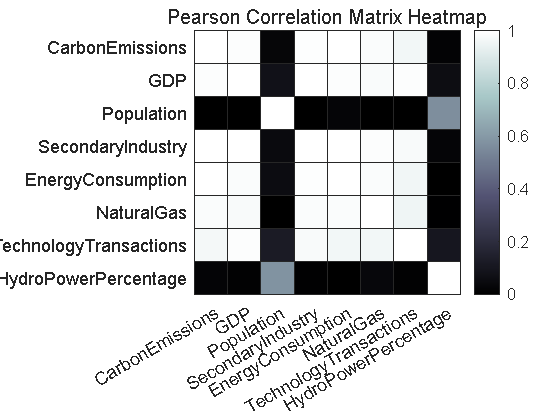


% 热力图
figure; % bone配色行 好看
%mycolor = [0.474509803921569,0.650980392156863,0.807843137254902;...
% 0.682352941176471,0.823529411764706,0.898039215686275;...
 %0.941176470588235,0.972549019607843,0.862745098039216;...
 %0.992156862745098,0.968627450980392,0.705882352941177;...
 %1,0.901960784313726,0.603921568627451];
h = heatmap(variableNames, variableNames, correlationMatrix);
h.Title = 'Pearson Correlation Matrix Heatmap';
h.Colormap = bone; 
h.ColorScaling = 'scaledcolumns'; 

%colormap(gca,mycolor);


% 创建数据表格
variableNames = {'LogCE','LogGDP', 'LogPopulation', 'LogSecond',  'LogEnergyConsumption', 'LogNaturalGas', 'LogTechnology', 'LogWaterPercent'};
dataTableLog = array2table(dataLog, 'VariableNames', variableNames);

% 拟合模型
lm_formula = 'LogCE ~ LogPopulation + LogGDP + LogSecond + LogEnergyConsumption + LogNaturalGas + LogTechnology + LogWaterPercent';
model = fitlm(dataTableLog, lm_formula);
disp(model);

线性回归模型:
    LogCE ~ 1 + LogGDP + LogPopulation + LogSecond + LogEnergyConsumption + LogNaturalGas + LogTechnology + LogWaterPercent

估计系数:
                             Estimate        SE         tStat       pValue 
                            __________    ________    __________    _______

    (Intercept)                 26.444      27.808       0.95094    0.35496
    LogGDP                  0.00015119     0.27532    0.00054916    0.99957
    LogPopulation              -2.2659      1.5165       -1.4941    0.15347
    LogSecond                  0.26351     0.40393       0.65236    0.52289
    LogEnergyConsumption       0.68352     0.45319        1.5082    0.14985
    LogNaturalGas            -0.016875    0.022403      -0.75325    0.46161
    LogTechnology             -0.02024    0.040531      -0.49936    0.62393
    LogWaterPercent           0.073633    0.053818        1.3682    0.18907


观测值数目: 25，误差自由度: 17
均方根误差: 0.0427
R 方: 0.995，调整 R 方 0.993
F 统计量(常量模型): 458，p 值 = 4.35e-18


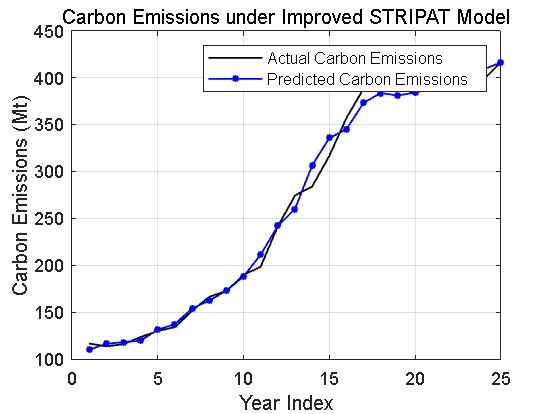


lmCoefficients = model.Coefficients.Estimate; % 存储系数
% 绘制结果曲线图
figure;
plot(exp(dataTableLog.LogCE), 'k', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Actual Carbon Emissions');
hold on;
predictedCE = predict(model, dataTableLog);
plot(exp(predictedCE), 'b-*', 'LineWidth', 1, 'MarkerSize', 4, 'DisplayName', 'Predicted Carbon Emissions');
title('Carbon Emissions under Improved STRIPAT Model');
xlabel('Year Index');
ylabel('Carbon Emissions (Mt)');
legend('show');
grid on;
hold off;

## 将预测得到的各个YPred的LSTM值带入到改良STRIPAT模型

YPredLogGDP = log(YPredGDP).';  
YPredLogPopulation = log(YPredPopulation).';
YPredLogSecond = log(YPredSecond).';
YPredLogEnergy = log(YPredEnergy).';
YPredLogNaturalGas = log(YPredNaturalgas).';
YPredLogTechnology = log(YPredTechnology).';
YPredLogWaterPercent = log(YPredWaterpercent).';
dataCE = dataTable.CarbonEmissions_mt(1:25); % 真实碳排放数据
Years = dataTable.Year(1:25); 

PredictedLogCE = lmCoefficients(1) + lmCoefficients(3) * YPredLogGDP + lmCoefficients(2) * YPredLogPopulation + ...
                 lmCoefficients(4) * YPredLogSecond + lmCoefficients(5) * YPredLogEnergy + ...
                 lmCoefficients(6) * YPredLogNaturalGas + lmCoefficients(7) * YPredLogTechnology + ...
                 lmCoefficients(8) * YPredLogWaterPercent;

PredictedCE_1 = exp(PredictedLogCE);
PredictedCE = (PredictedCE_1)/1e3+300;
% 输出预测结果
disp('Predicted CarbonEmissions for future years:');

Predicted CarbonEmissions for future years:


disp(PredictedCE);

  409.0743
  400.4711
  394.9108
  391.3445
  389.0474
  387.5450
  386.5415
  385.8570
  385.3810
  385.0442
  384.8024
  384.6272
  384.4990
  384.4043
  384.3336
  384.2804
  384.2397
  384.2081
  384.1830
  384.1623
  384.1448
  384.1290
  384.1145
  384.1006
  384.0872
  384.0732
  384.0590
  384.0440



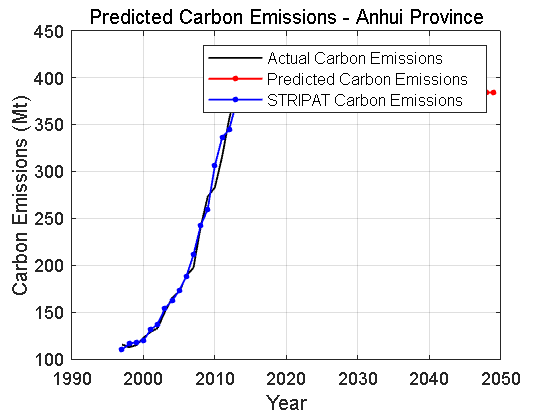

% 实际与预测的碳排放量对比
figure;
plot(Years, dataCE, 'k', 'LineWidth', 1, 'MarkerSize',3 , 'DisplayName', 'Actual Carbon Emissions');
hold on;
plot(Years(1) + (25:52), PredictedCE, 'r*-', 'LineWidth', 1, 'MarkerSize', 3, 'DisplayName', 'Predicted Carbon Emissions');
%STRIPATPred=exp(PredictedCE);
plot(Years(1)+ (0:24), exp(predictedCE), 'b-*', 'LineWidth', 1, 'MarkerSize', 3, 'DisplayName', 'STRIPAT Carbon Emissions');
title('Predicted Carbon Emissions - Anhui Province');
xlabel('Year');
ylabel('Carbon Emissions (Mt)');
legend show;
grid on;
hold off;